close all
clear variables
data = importdata('C:\Users\hp\Desktop\Panasik\MatLab\data.txt')

data =      6
    14
    28
    38
    46
    59
    63
    75
    83
    91


settings = importdata('C:\Users\hp\Desktop\Panasik\MatLab\settings.txt')

settings =     0.0460
    0.0125



n = length(data)

n = 224


dT = settings(1)

dT = 0.0460

dV = settings(2)

dV = 0.0125


time = ((1:n)*dT)'

time =     0.0460
    0.0920
    0.1380
    0.1840
    0.2300
    0.2760
    0.3220
    0.3680
    0.4140
    0.4600


voltage = data * dV

voltage =     0.0750
    0.1750
    0.3500
    0.4750
    0.5750
    0.7375
    0.7875
    0.9375
    1.0375
    1.1375



[max_V, t_max] = max(voltage)

max_V = 3.0500

t_max = 147

t_up = t_max*dT

t_up = 6.7620

t_down = time(end) - t_max*dT

t_down = 3.5420


fig = figure("Name", "Панасик Александра, Б03-004")

fig =   Figure (1: Панасик Александра, Б03-004) with properties:

      Number: 1
        Name: 'Панасик Александра, Б03-004'
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


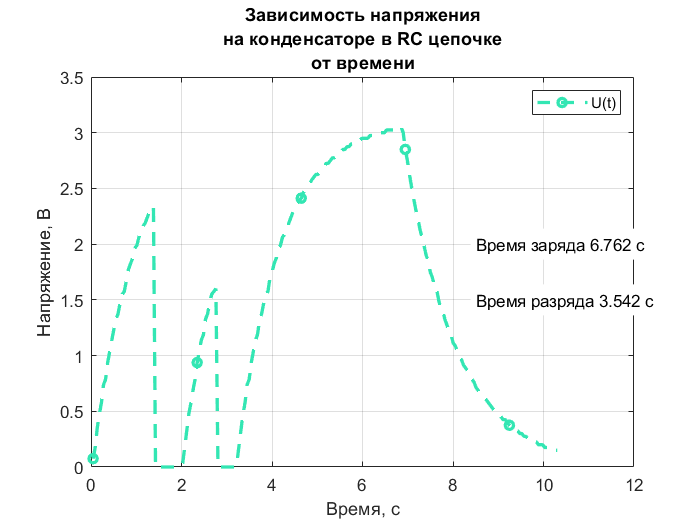

plot(time, voltage, "b--o", "MarkerIndices", 1:50:n, 'LineWidth', 2, 'MarkerSize', 5, 'Color', [0.2 0.9 0.7])
grid on
title({'Зависимость напряжения', 'на конденсаторе в RC цепочке', 'от времени'})
xlabel("Время, с")
ylabel("Напряжение, В")
set(gcf,'Visible','on')
legend("U(t)")
text(8.5, 2, ['Время заряда ', num2str(t_up), ' с'], "BackgroundColor", 'w')
text(8.5, 1.5, ['Время разряда ', num2str(t_down), ' с'], "BackgroundColor", 'w' )

saveas(fig, "capacitor.svg")
saveas(fig, "capacitor.png")